%% ===============================================================
%  STEP 1 - Importación y visualización profesional del experimento
%  Archivo: analisis_bomba_step1_import.m
%
%  Objetivo:
%    - Cargar los datos del barrido de la bomba
%    - Convertir el tiempo a segundos
%    - Imprimir información básica para el reporte
%    - Generar gráficas estilo artículo científico
% ================================================================

clear; clc; close all;

%% ===============================================================
%  1) CONFIGURACIÓN DEL ARCHIVO
% ===============================================================
nombreArchivo = 'datos_barrido_Com_N.csv';   % <-- asegúrate que está en la carpeta

%% ===============================================================
%  2) IMPORTAR LOS DATOS DEL CSV
% ===============================================================
data = readtable(nombreArchivo);

% Ajusta los nombres si son distintos en tu archivo
t_ms       = data.t_ms;          % tiempo en milisegundos
u_pwm      = data.PWM;           % señal PWM
p_kPa      = data.Presion_kPa;   % presión en kPa

% Convertir a segundos
t_s = t_ms / 1000.0;

%% ===============================================================
%  3) INFORMACIÓN BÁSICA DEL EXPERIMENTO
% ===============================================================
fprintf('\n--- INFORMACIÓN DEL EXPERIMENTO ---\n');


--- INFORMACIÓN DEL EXPERIMENTO ---


fprintf('Número de muestras: %d\n', length(t_s));

Número de muestras: 26400


fprintf('Tiempo total: %.3f s\n', t_s(end) - t_s(1));

Tiempo total: 263.990 s



Ts_prom = mean(diff(t_s));
fprintf('Periodo de muestreo promedio: %.4f s (%.1f ms)\n', Ts_prom, Ts_prom*1000);

Periodo de muestreo promedio: 0.0100 s (10.0 ms)



fprintf('PWM:      min = %.1f, max = %.1f\n', min(u_pwm), max(u_pwm));

PWM:      min = 0.0, max = 255.0


fprintf('Presión:  min = %.3f kPa, max = %.3f kPa\n\n', min(p_kPa), max(p_kPa));

Presión:  min = -34.637 kPa, max = 0.913 kPa



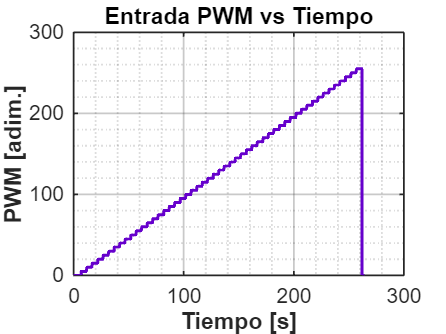


%% ===============================================================
%  4) PARÁMETROS DE GRAFICACIÓN PROFESIONAL
% ===============================================================

LW   = 2.0;      % grosor de línea
FS   = 14;       % tamaño de fuente
FSbig = 16;      % tamaño para títulos
morado = [0.4 0 0.8];   % color elegante (IEEE friendly)

%% ===============================================================
%  5) GRÁFICA 1: PWM VS TIEMPO (estilo científico)
% ===============================================================

figure('Name','PWM vs Tiempo','Color','w');

plot(t_s, u_pwm, 'LineWidth', LW, 'Color', morado);
grid on; grid minor;

xlabel('Tiempo [s]', 'FontSize', FS, 'FontWeight','bold');
ylabel('PWM [adim.]', 'FontSize', FS, 'FontWeight','bold');
title('Entrada PWM vs Tiempo', 'FontSize', FSbig, 'FontWeight','bold');

ax = gca;
ax.FontSize = FS;
ax.LineWidth = 1.2;
ax.GridAlpha = 0.25;
ax.MinorGridAlpha = 0.15;
ax.Box = 'on';

%Guardar Imagen
print('fig_PWM_tiempo','-dpng','-r300');

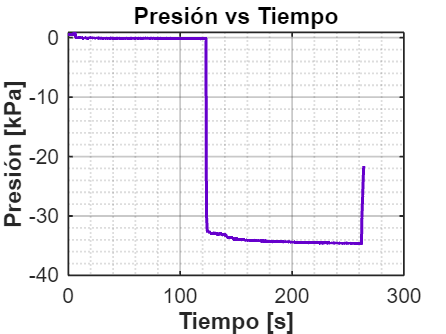


%% ===============================================================
%  6) GRÁFICA 2: PRESIÓN VS TIEMPO (estilo científico)
% ===============================================================

figure('Name','Presion vs Tiempo','Color','w');

plot(t_s, p_kPa, 'LineWidth', LW, 'Color', morado);
grid on; grid minor;

xlabel('Tiempo [s]', 'FontSize', FS, 'FontWeight','bold');
ylabel('Presión [kPa]', 'FontSize', FS, 'FontWeight','bold');
title('Presión vs Tiempo', 'FontSize', FSbig, 'FontWeight','bold');

ax = gca;
ax.FontSize = FS;
ax.LineWidth = 1.2;
ax.GridAlpha = 0.25;
ax.MinorGridAlpha = 0.15;
ax.Box = 'on';

%% ===============================================================
%  7) OPCIONAL: GUARDAR FIGURAS PARA EL REPORTE
% ===============================================================

print('fig_Presion_tiempo','-dpng','-r300');